Hello doston aaj hum BT readings lenge

Chalo shuru karte hain

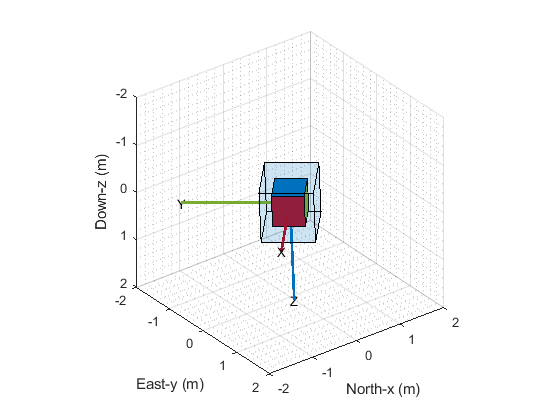

%table for sensor data
sensorData = array2table(zeros(1, 10));
sensorData(1, :) = [];

%Initialise filter
Fs = 10;
decim = 1;
fuse = ahrsfilter("SampleRate", 10, "DecimationFactor", decim);

%Initialise pose plot
pp = poseplot;
xlabel("North-x (m)");
ylabel("East-y (m)");
zlabel("Down-z (m)");
xlim([-2.00 2.00]);
ylim([-2.00 2.00]);
zlim([-2.00 2.00]);
pos = [0 0 0];

% Define BlueTooth object. The exact name is required
esp32 = bluetooth("Shobhit_ESP32", 1);
esp32.configureTerminator("CR");
collectVal = 1;
esp32.writeline("hello");
watchdog = 0;

while (collectVal)
    a = esp32.NumBytesAvailable;
    if(a > 0)
        data = esp32.readline();
        watchdog = 0;
        sensorDataNew = cell2mat(arrayfun(@str2num,transpose(split(data)),'uni',0));
        %sensorDataNew = array2table(sensorDataNew(1:10));
        % Accel, Gyro, Magneto
        q = fuse(sensorDataNew(5:7)*9.81, sensorDataNew(2:4)*(pi/180), sensorDataNew(8:10));
        set(pp, Orientation = q, Position = pos);
        drawnow
    else
        watchdog = watchdog + 1;
    end

    if (watchdog > 50000)
        break;
    end

    pause(0.0001);

end


%sensorData.Properties.VariableNames = ["time", "gx", "gy", "gz", "ax", "ay", "az", "mx", "my", "mz"];
%disp(sensorData);
%save mpu9250new.mat sensorData;

%cleanup
disp("Exiting data collection loop. Clearing all variables now");

Exiting data collection loop. Clearing all variables now


clear;
